# Familiarization with odometry data

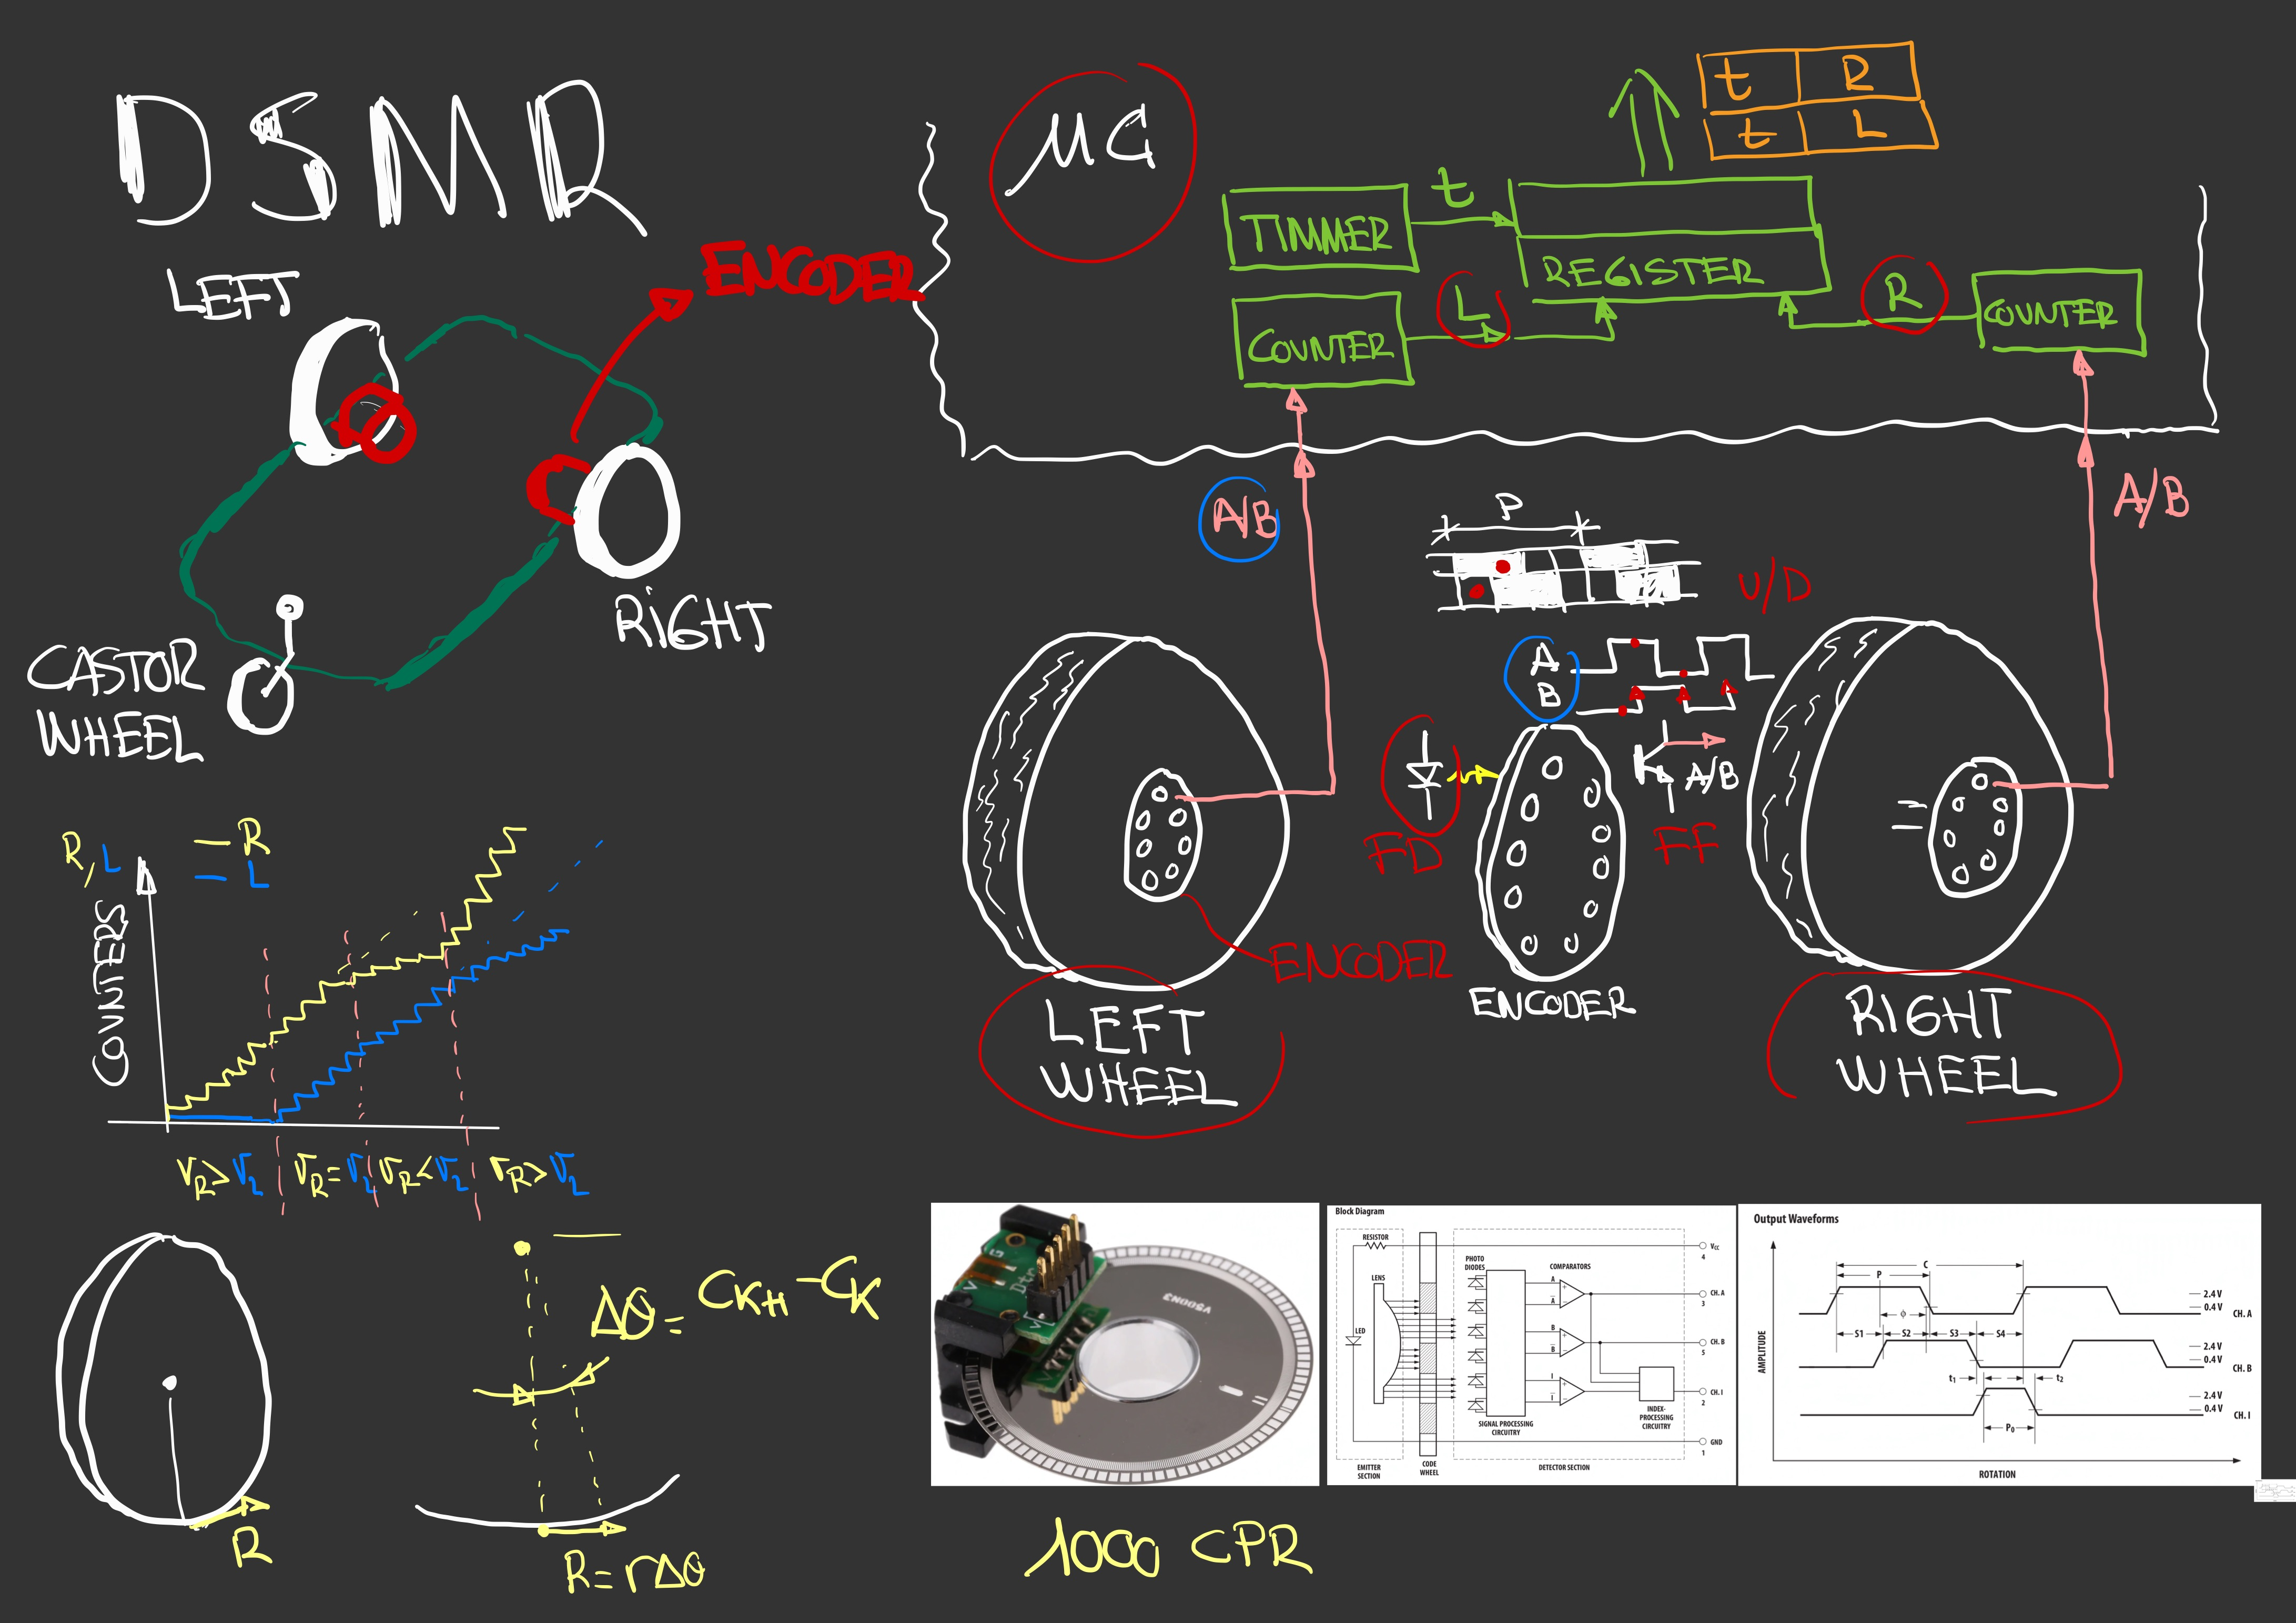

## Load and visualize data

clear
load('Encoder_Data.mat')

**R_acu & L_acu**: The microcontroller counter report; firts column time stamp, second column the total displacement of right and left wheel in meters. 

R_acu

R_acu =          0         0
    0.0200         0
    0.0400         0
    0.0600         0
    0.0800         0
    0.1000         0
    0.1200         0
    0.1400         0
    0.1600         0
    0.1800         0


L_acu

L_acu =          0         0
    0.0200         0
    0.0400         0
    0.0600         0
    0.0800         0
    0.1000         0
    0.1200         0
    0.1400         0
    0.1600         0
    0.1800         0


**Ts & Tf **: Sample time and total experiment time (Tf=Numbers of rows *Ts) in [s]

Ts

Ts = 0.0200

Tf

Tf = 60.0800

Tf=length(R_acu(:,2))*Ts

Tf = 60.0800

ts=diff(R_acu(:,1)) % it is constant

ts =     0.0200
    0.0200
    0.0200
    0.0200
    0.0200
    0.0200
    0.0200
    0.0200
    0.0200
    0.0200


**r_w & W:** Mobile Robot paramenters; wheel radius and distance between wheels in [m]

r_w

r_w = 0.0947

W

W = 0.5200

W % 2S

W = 0.5200

## Plotting encoders data with respect time 

t=R_acu(:,1)

t =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


t=(0:Ts:Tf-Ts)'

t =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


t=linspace(0,Tf,length(R_acu(:,2)))'

t =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1601
    0.1801


### Total wheel displacements profile

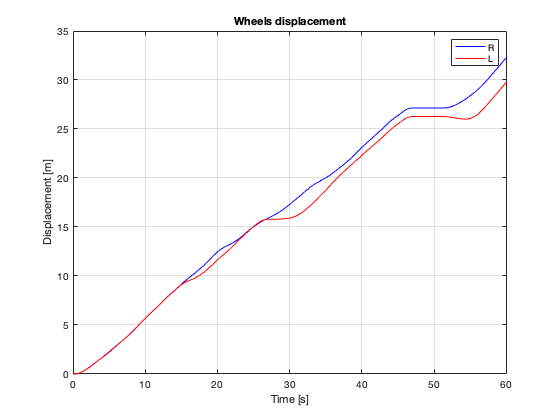

figure
plot(t,R_acu(:,2),'b')
hold on 
plot(t,L_acu(:,2),'r') 
xlim ([0 Tf])
grid on
title('Wheels displacement')
xlabel ('Time [s]')
ylabel ('Displacement [m]')
legend('R','L')

## Wheel incremental displacements

It tell us how much displacement did the wheel during a sample time.


$$R_{\textrm{inc}} =R_{k+1} -R_k$$



$$L_{\textrm{inc}} =L_{k+1} -L_k$$


R_inc=diff(R_acu(:,2)) 

R_inc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


L_inc=diff(L_acu(:,2))

L_inc =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


### Incremental displacements profile

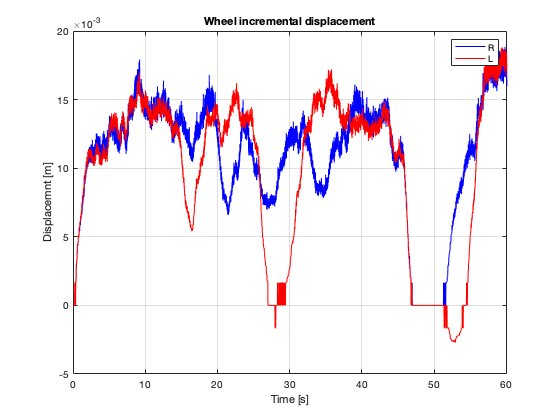

figure
plot(t(1:end-1),R_inc,'b') % We losted one sample with 'diff' command
hold on 
plot(t(1:end-1),L_inc,'r') % We losted one sample with 'diff' command
hold on 
xlim ([0 Tf])
grid on
title('Wheel incremental displacement')
xlabel ('Time [s]')
ylabel ('Displacemnt [m]')
legend('R','L')

### Wheel velocities profile


$$\textrm{Velocity}=\frac{\Delta \textrm{displacemts}}{\Delta \textrm{time}}=\frac{\Delta e}{\Delta t}=\frac{\Delta R}{T_s }=\frac{R_{\textrm{inc}} }{T_s }$$


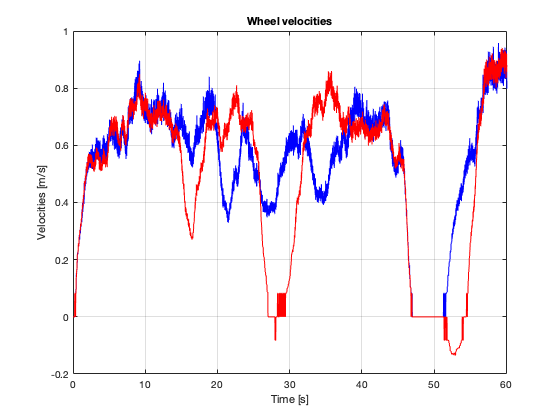

figure
plot(t(1:end-1),R_inc/Ts,'b')
hold on 
plot(t(1:end-1),L_inc/Ts,'r') 
xlim ([0 Tf])
grid on
title('Wheel velocities')
xlabel ('Time [s]')
ylabel ('Velocities [m/s]')

### Equivalence of Encoder Data

Some time the microcontroller gives wheels increment displacement. To recover total wheel displacement


$$R_{{\textrm{acu}}_k } =\int_0^{t_k } R_{\textrm{inc}} \left(t\right)\textrm{dt}\equiv \sum_i^k R_{{\textrm{inc}}_i }$$


R_ac=cumsum(R_inc,1)

R_ac =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


L_ac=cumsum(L_inc,1)

L_ac =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


### Recovered wheel displacements profile

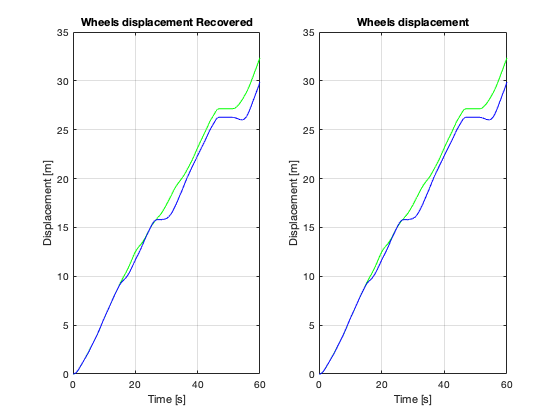

figure
subplot(1,2,1)
plot(t(1:end-1),R_ac,'g')
hold on 
plot(t(1:end-1),L_ac,'b') 
xlim ([0 Tf])
grid on
title('Wheels displacement Recovered')
xlabel ('Time [s]')
ylabel ('Displacement [m]')
subplot(1,2,2)
plot(t,R_acu(:,2),'g')
hold on
plot(t,L_acu(:,2),'b')
xlim ([0 Tf])
grid on
title('Wheels displacement')
xlabel ('Time [s]')
ylabel ('Displacement [m]')

## Odometry

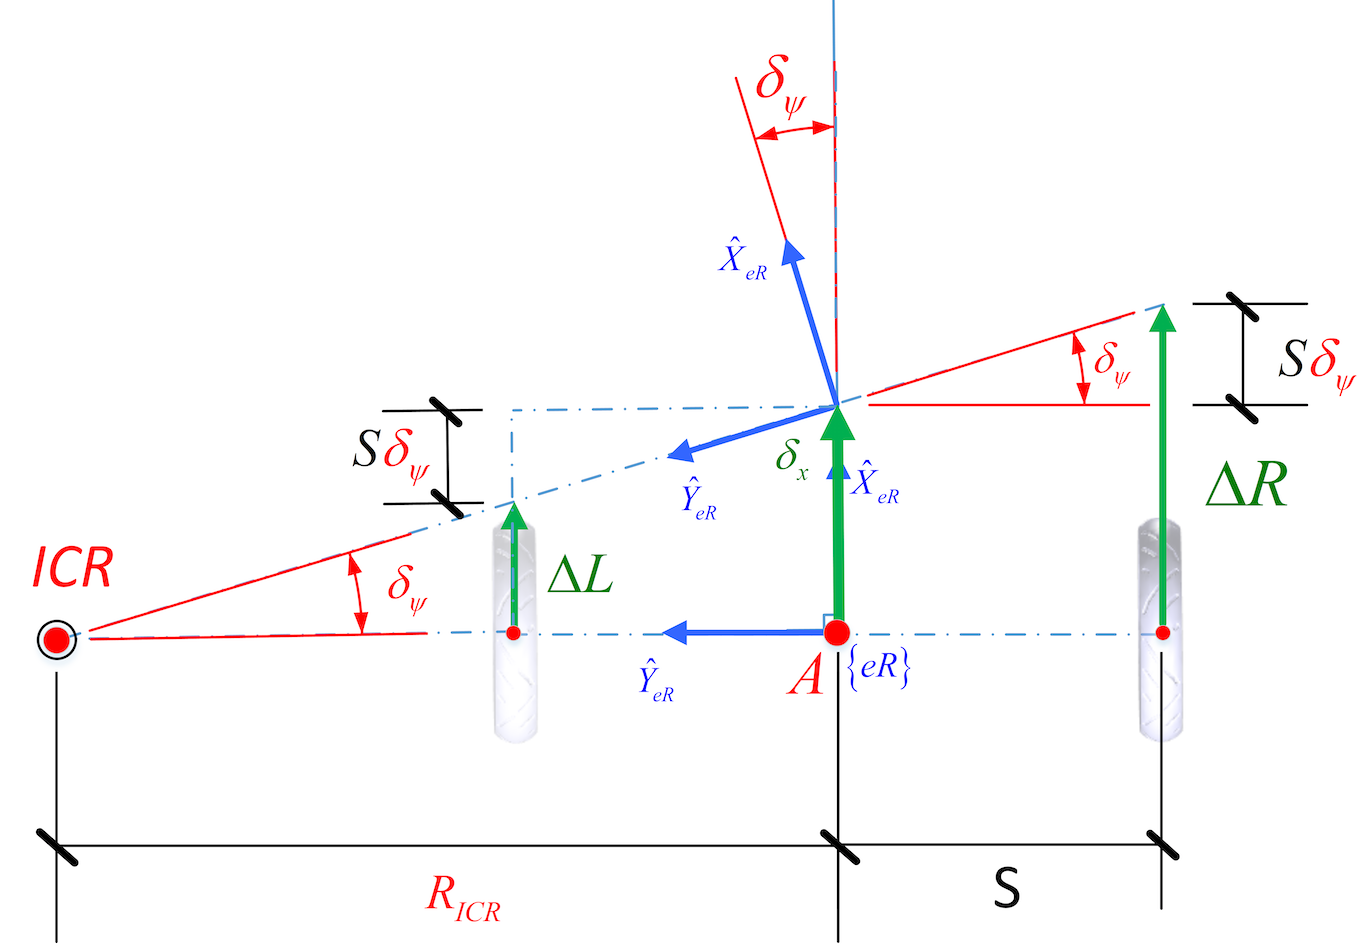


$$\delta_{x} =\frac{R_{inc}+L_{inc}}{2} $$



$$\delta_{\Psi} =\frac{R_{inc}-L_{inc}}{2S} $$


 delta_d=(R_inc+L_inc)/2

delta_d =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


 delta_t=(R_inc-L_inc)/W

delta_t =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


### Pose integration

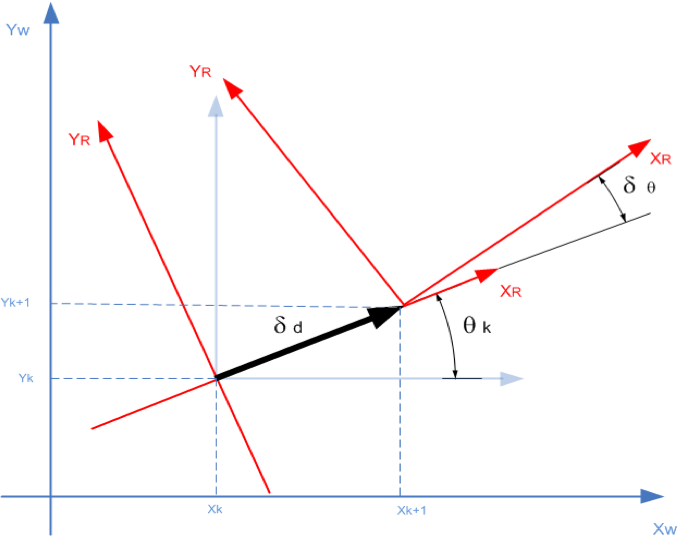

Using post multiplication 

Pose;  ${\xi _k} = \left( {\begin{array}{*{20}{c}}
  {{c} {\theta _k}}&{ - s{\theta _k}}&{{x_k}} \\ 
  {s{\theta _k}}&{{c} {\theta _k}}&{{y_k}} \\ 
  0&0&1 
\end{array}} \right)\]$

Next pose; $% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCaebbnrfifHhDYfgasaacH8sr
% ps0lbbf9q8WrFfeuY-ribbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-
% yr0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dc9Gqpi0d
% meaabaqaciGacaGaaeqabaWaaeaaeaaakeaacqaH+oaEdaWgaaWcba
% Gaam4AaiabgUcaRiaaigdaaeqaaOGaeyypa0JaeqOVdG3aaSbaaSqa
% aiaadUgaaeqaaOGaciiDaiaacggacaGGUbGaam4CaiaadYgadaWgaa
% WcbaGaamiEaaqabaGcdaqadaqaaiabes7aKnaaBaaaleaacaWGKbaa
% beaaaOGaayjkaiaawMcaaiaadkfacaWGVbGaamiDamaaBaaaleaaca
% WGAbaabeaakmaabmaabaGaeqiTdq2aaSbaaSqaaiabeI7aXbqabaaa
% kiaawIcacaGLPaaaaaa!4D21!
\[{\xi _{k + 1}} = {\xi _k}\tan s{l_x}\left( {{\delta _d}} \right)Ro{t_Z}\left( {{\delta _\theta }} \right)\]$

Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2)

Initial_pose =          0    1.0000         0    8.6500
   -1.0000         0         0   17.2000
         0         0    1.0000         0
         0         0         0    1.0000


Pose(:,:,1)=Initial_pose;
 for i=1:length(t)-1
    Pose(:,:,i+1)=Pose(:,:,i)*transl(delta_d(i),0,0)*trotz(delta_t(i));
    %Pose(:,:,i+1)=Pose(:,:,i)*trotz(delta_t(i))*transl(delta_d(i),0,0);
    Position(:,i+1)=transl(Pose(:,:,i));
    Orientation(:,i+1)=tr2rpy(Pose(:,:,i));
 end

or using 


$$% MathType!MTEF!2!1!+-
% faaahqart1ev3aaaKnaaaaWenf2ys9wBH5garuavP1wzZbItLDhis9
% wBH5garmWu51MyVXgaruWqVvNCPvMCaebbnrfifHhDYfgasaacH8sr
% ps0lbbf9q8WrFfeuY-ribbf9v8qqaqFr0xc9pk0xbba9q8WqFfea0-
% yr0RYxir-Jbba9q8aq0-yq-He9q8qqQ8frFve9Fve9Ff0dc9Gqpi0d
% meaabaqaciGacaGaaeqabaWaaeaaeaaakeaacqaH+oaEdaWgaaWcba
% Gaam4AaiabgUcaRiaaigdaaeqaaOGaeyypa0ZaaeWaaeaafaWabeGa
% baaabaGaamiCamaaBaaaleaacaWGRbGaey4kaSIaaGymaaqabaaake
% aacqaH4oqCdaWgaaWcbaGaam4AaiabgUcaRiaaigdaaeqaaaaaaOGa
% ayjkaiaawMcaaiabg2da9maabmaabaqbaeqabmqaaaqaaiaadIhada
% WgaaWcbaGaam4AaaqabaGccqGHRaWkcqaH0oazdaWgaaWcbaGaamiz
% aaqabaGccaWGJbGaeqiUde3aaSbaaSqaaiaadUgaaeqaaaGcbaGaam
% yEamaaBaaaleaacaWGRbaabeaakiabgUcaRiabes7aKnaaBaaaleaa
% caWGKbaabeaakiaadohacqaH4oqCdaWgaaWcbaGaam4Aaaqabaaake
% aacqaH4oqCdaWgaaWcbaGaam4AaaqabaGccqGHRaWkcqaH0oazdaWg
% aaWcbaGaeqiUdehabeaaaaaakiaawIcacaGLPaaaaaa!5DEC!
\[{\xi _{k + 1}} = \left( {\begin{array}{*{20}{c}}
  {{p_{k + 1}}} \\ 
  {{\theta _{k + 1}}} 
\end{array}} \right) = \left( {\begin{array}{*{20}{c}}
  {{x_k} + {\delta _d}c{\theta _k}} \\ 
  {{y_k} + {\delta _d}s{\theta _k}} \\ 
  {{\theta _k} + {\delta _\theta }} 
\end{array}} \right)\]$$


 Initial_position=transl(Initial_pose)

Initial_position =     8.6500
   17.2000
         0


 Initial_orientation=-pi/2

Initial_orientation = -1.5708

 x(1)=Initial_position(1)+0.05 % for comparing reasons we offset x by 5cm

x = 8.7000

 y(1)=Initial_position(2)

y = 17.2000

 o(1)=Initial_orientation

o = -1.5708

 for i=1:(length(t)-1)
    x(i+1)= x(i)+delta_d(i)*cos(o(i));
    y(i+1)= y(i)+delta_d(i)*sin(o(i));
    o(i+1)=o(i)+delta_t(i);
    end

### Displaying trajectory

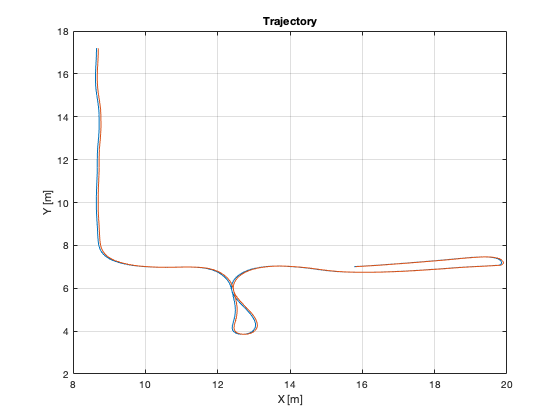

figure
plot(Position(1,2:end),Position(2,2:end))
grid on
hold on
title('Trajectory')
xlabel ('X [m]')
ylabel ('Y [m]')
plot(x,y)

### Understanding Orientation

Think about $\sin \left(-\frac{\pi }{2}\right)=\sin \left(\frac{3}{2}\pi \right)=\sin \left(2\pi +\frac{3}{2}\pi \right)$

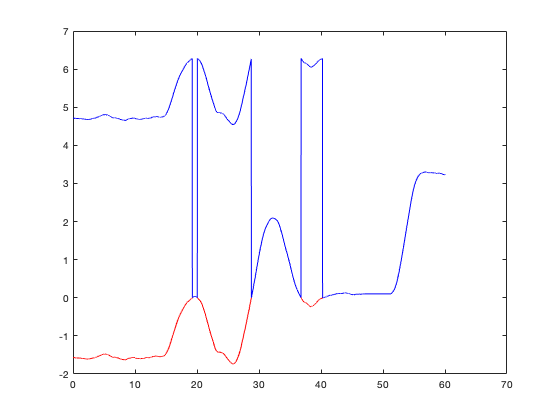

figure
plot(t,o,'r')
hold on
plot(t,mod(o,2*pi),'b')

### Plotting the enviroment and trajectory

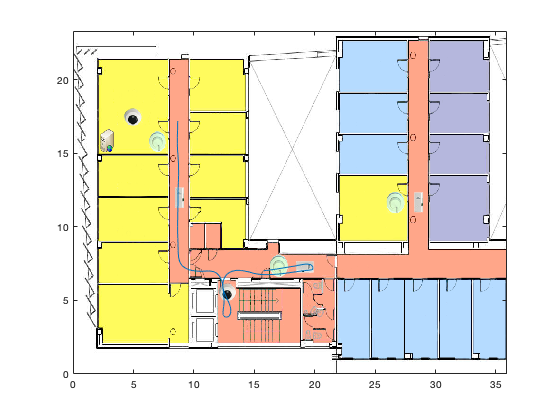

figure1=figure
I=imread('Enviroment.png');
x_ima=[0 35.9];
y_ima=[23.31 0];
image(I,'XData',x_ima,'YData',y_ima);
axis xy
hold on
plot(Position(1,2:end),Position(2,2:end))

## Uncertanty: Adding noise


$$\delta_{d} =\frac{R+L}{2}+\nu_{d}$$



$$\delta_{\theta} =\frac{R-L}{2S} +\nu_{\theta}$$


Noise in the odometry displacement

 delta_d_n=((R_inc+L_inc)/2)+randn((length(t)-1),1)*0.005

delta_d_n =    -0.0005
   -0.0012
    0.0016
    0.0016
   -0.0043
   -0.0002
   -0.0008
    0.0031
    0.0055
    0.0055


Noise in the odometry change of orientation

 delta_t_n=((R_inc-L_inc)/W)+randn((length(t)-1),1)*0.005 

delta_t_n =     0.0046
   -0.0026
   -0.0065
   -0.0000
    0.0012
   -0.0021
   -0.0073
    0.0060
    0.0010
   -0.0035


### Displacement noise visualization

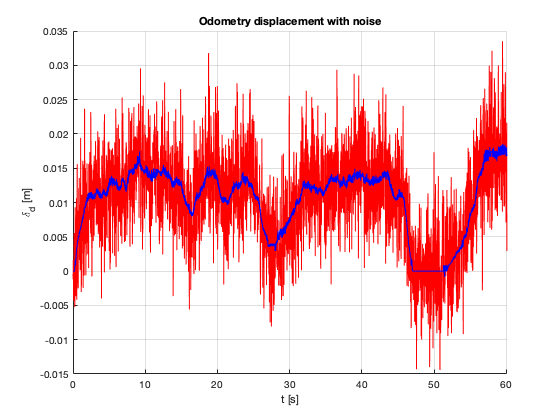

figure
hold on
plot(t(1:end-1),delta_d_n,'r')
xlim ([0 Tf])
grid on
title('Odometry displacement with noise')
xlabel ('t [s]')
ylabel ('\delta_d [m]')
plot(t(1:end-1),delta_d,'b')

Orientation noise visualization

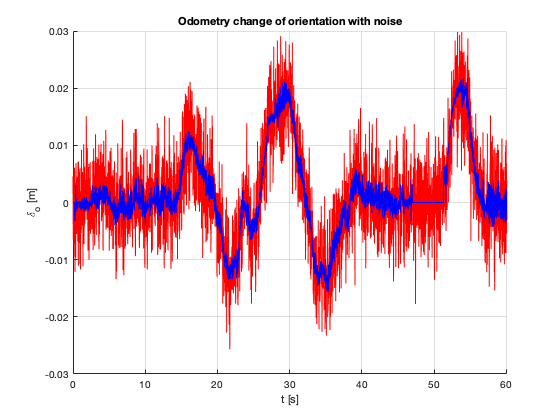

figure
hold on
plot(t(1:end-1),delta_t_n,'r')
xlim ([0 Tf])
grid on
title('Odometry change of orientation with noise')
xlabel ('t [s]')
ylabel ('\delta_o [m]')
plot(t(1:end-1),delta_t,'b')

## Pose integration with noise

Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2)

Initial_pose =          0    1.0000         0    8.6500
   -1.0000         0         0   17.2000
         0         0    1.0000         0
         0         0         0    1.0000


Pose_n(:,:,1)=Initial_pose;
 for i=1:length(t)-1
    Pose_n(:,:,i+1)=Pose_n(:,:,i)*transl(delta_d_n(i),0,0)*trotz(delta_t_n(i));
    Position_n(:,i+1)=transl(Pose_n(:,:,i));
    Orientation_n(:,i+1)=tr2rpy(Pose_n(:,:,i));
 end

## Comparing  trajectories

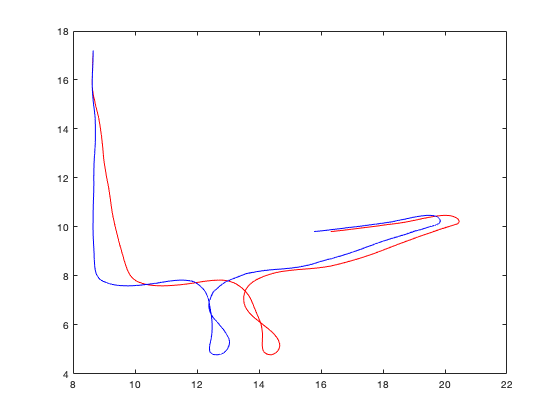

 figure
 plot(Position_n(1,2:end),Position_n(2,2:end),'r')
 hold on
 plot(Position(1,2:end),Position_n(2,2:end),'b')

## Ellipse error

It is of interest to launch many time the dices (our trajectory with noise) and check for the last position and orientation 

Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2)

Initial_pose =          0    1.0000         0    8.6500
   -1.0000         0         0   17.2000
         0         0    1.0000         0
         0         0         0    1.0000


Pose_n(:,:,1)=Initial_pose;
for j=1:1000
delta_d_n=((R_inc+L_inc)/2)+randn((length(t)-1),1)*0.005; %Dices again
delta_t_n=((R_inc-L_inc)/W)+randn((length(t)-1),1)*0.005; 
 for i=1:length(t)-1
    Pose_n(:,:,i+1)=Pose_n(:,:,i)*transl(delta_d_n(i),0,0)*trotz(delta_t_n(i));
    Position_n(:,i+1)=transl(Pose_n(:,:,i));
    Orientation_n(:,i+1)=tr2rpy(Pose_n(:,:,i));
 end
 Positions_n(:,j)=Position_n(:,end);
 Orientations_n(:,j)=Orientation_n(:,end);
end

### Visualizing the experimental ellipse error of final position

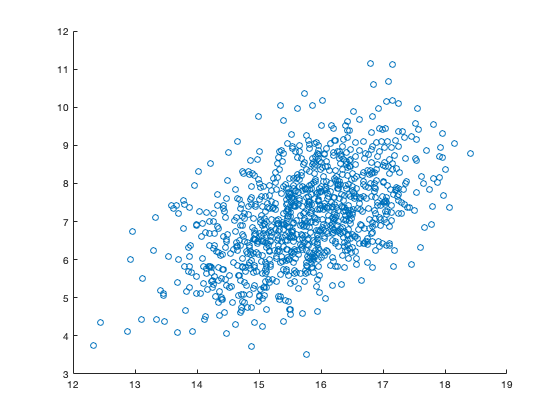

figure
scatter(Positions_n(1,:),Positions_n(2,:))